# Make synthetic seismograms (based on FSM)

## Introduction

This script generates synthetic seismograms. 

For traveltime modeling, the FSM method is used. 

Synthetic seismograms are compared with FD results. 

**Author**: Abakumov Ivan

Freie Universität Berlin

**Publication date**: 22nd September 2017

**E-mail**: [abakumov_ivan@mail.ru](mailto:abakumov_ivan@mail.ru)

## Add MLIB library

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## Set parameters of FD modeling

folder = [mlibfolder '/Examples/Heidimod/s90900/'];
vp = 4000;                  % velocity of P-wave
vs = 2350;                  % velocity of S-wave
rho = 3000;                 % dencity 
ns = 130;                   % number of time samples
nts = 20;                   % number of time samples of the wavelet
dt = 0.002;                 % time step
nrec = 8;                   % number of receivers
f = 40;                     % dominant frequency

## Make G-file

G=GridClass;

% [m]        [m]          [m]          [s]
G.x0=0;      G.y0=0;      G.z0=0;      G.t0 = 0.00;        % initial point
G.nx=102;    G.ny=103;    G.nz=101;    G.nt = ns;          % grid size
G.dx=10;     G.dy=10;     G.dz=10;     G.dt = dt;          % grid step (meter)

G.gridInfo;

Information about grid:
x0=0, dx=10, Nx=102.
y0=0, dy=10, Ny=103.
z0=0, dz=10, Nz=101.
t0=0, dt=0.002, Nt=130.


G.setGrid;
Gold = oldGrid(G);

## Read results of FD modeling: source and receiver positions

fid = fopen([folder 'slocation'],'r');
sloc = fread(fid, inf, 'single', 'ieee-be');
fclose(fid);

fid = fopen([folder 'geoloc'],'r');
gloc = fread(fid, inf, 'single', 'ieee-be');
fclose(fid);
gloc = reshape(gloc,[3,nrec]);

acq.gsx = sloc(2,:); 
acq.gsy = sloc(3,:); 
acq.gsz = sloc(1,:);
acq.grx = gloc(2,:); 
acq.gry = gloc(3,:); 
acq.grz = gloc(1,:);
acq.sx = G.x0 + (acq.gsx-1)*G.dx;
acq.sy = G.y0 + (acq.gsy-1)*G.dy;
acq.sz = G.z0 + (acq.gsz-1)*G.dz;
acq.rx = G.x0 + (acq.grx-1)*G.dx;
acq.ry = G.y0 + (acq.gry-1)*G.dy;
acq.rz = G.z0 + (acq.grz-1)*G.dz;

clear sloc gloc

## Read results of FD modeling: seismograms

fid = fopen([folder 'arbxseis'],'r');
datax = fread(fid, inf, 'single', 'ieee-be');
fclose(fid);

fid = fopen([folder 'arbyseis'],'r');
datay = fread(fid, inf, 'single', 'ieee-be');
fclose(fid);

fid = fopen([folder 'arbzseis'],'r');
dataz = fread(fid, inf, 'single', 'ieee-be');
fclose(fid);

datax = reshape(datax,[nrec ns 1]); 
datay = reshape(datay,[nrec ns 1]); 
dataz = reshape(dataz,[nrec ns 1]);

## Read results of FD modeling: wavelet

fid = fopen([folder 'wavelet'],'r');
data = fread(fid, inf, 'single', 'ieee-be');
fclose(fid);
wavelet=reshape(data,[20,6,1]);
% wavelet 1 -- zz -- M33*ricker
% waveler 2 -- xx -- M11*ricker
% wavelel 3 -- zx -- M13 - M31*ricker
% wavelet 4 -- yy -- M22*ricker
% wavelet 5 -- zy -- M23 - M32*recker
% waverel 6 -- xy -- M12 - M21*ricker

## Moment tensor

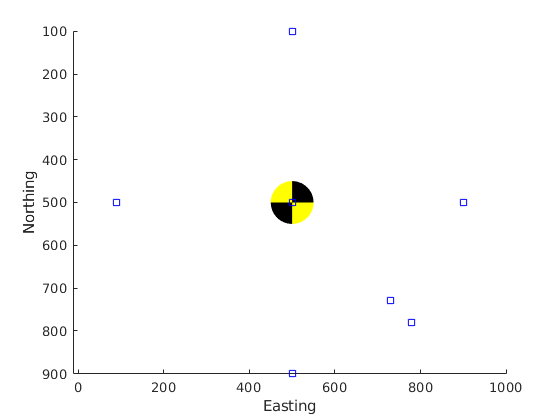

%M = [-.773 0.602 -0.041;0.602 0.729 0.266;-0.041 0.266 0.044]; 
M = [0 -1 0;-1 0 0;0 0 0]; 
%M = [0 0 1;0 0 0;1 0 0]; 
%M = compute_potency(45,45,0); 
u = compute_displacement_iso(M,[1 .5]); 

figure(2)
classic_beachball(u,[acq.sx,acq.sy,acq.sz],50); 
hold on; 
plot3(acq.rx,acq.ry,acq.rz,'bs'); 
xlabel('Easting'); 
ylabel('Northing'); 
zlabel('Depth'); 
view([0 0 -1])

## Make velocity model and compute traveltimes of P- and S- waves

Pvelmod = 4000*ones(G.nx,G.ny,G.nz); 
Svelmod = 2350*ones(G.nx,G.ny,G.nz); 

S = [acq.sx, acq.sy, acq.sz]; 
Ptti = FSM3D(Gold, S, Pvelmod); 
Stti = FSM3D(Gold, S, Svelmod);

## Build synthethic wavelet

T = linspace((-nts/2+1)*G.dt, nts/2*G.dt, nts);
ww= -2e20.*(2.0*pi*f)*T.*exp(-(2*T*pi*f).^2); 
ww = ww';
ww2 = -diff(ww,2)/G.dt^2;
%plot(ww)

## Compute synthetic seismogram

seis = zeros(nrec,ns,3);  

for r = 1:length(acq.rx)
    
    % add P-wave
    tp = Ptti(acq.grx(r),acq.gry(r),acq.grz(r));

    n_p = [(Ptti(acq.grx(r)+1,acq.gry(r),acq.grz(r)) - Ptti(acq.grx(r)-1,acq.gry(r),acq.grz(r)))/2/G.dx,...
         (Ptti(acq.grx(r),acq.gry(r)+1,acq.grz(r)) - Ptti(acq.grx(r),acq.gry(r)-1,acq.grz(r)))/2/G.dy,...
         (Ptti(acq.grx(r),acq.gry(r),acq.grz(r)+1) - Ptti(acq.grx(r),acq.gry(r),acq.grz(r)-1))/2/G.dz];
    
    n_p  = n_p/norm(n_p); 
 
    up = n_p*M*n_p';
    
    dispp = up/(4*pi*rho*vp^3*tp).*n_p; 
    gtp = x2grid(tp,G.t0, G.dt, G.nt);
    seis(r,(gtp+1):(gtp+18),:) = ww2*dispp; 
    
    % add S-wave
    ts = Stti(acq.grx(r),acq.gry(r),acq.grz(r));
        
    n_s = [(Stti(acq.grx(r)+1,acq.gry(r),acq.grz(r)) - Stti(acq.grx(r)-1,acq.gry(r),acq.grz(r)))/2/G.dx,...
          (Stti(acq.grx(r),acq.gry(r)+1,acq.grz(r)) - Stti(acq.grx(r),acq.gry(r)-1,acq.grz(r)))/2/G.dy,...
          (Stti(acq.grx(r),acq.gry(r),acq.grz(r)+1) - Stti(acq.grx(r),acq.gry(r),acq.grz(r)-1))/2/G.dz];

    n_s  = n_s/norm(n_s); 

    us = zeros(1,3); 
    for i=1:3
        for j=1:3
            for k = 1:3
                us(i) = us(i) + (kronecker(i,j) - n_s(i)*n_s(j)) * n_s(k)*M(j,k); 
            end
        end
    end
%    tem(r) = us
    disps = us/(4*pi*rho*vs^3*ts); 
    gts = x2grid(ts,G.t0, G.dt, G.nt);
    seis(r,(gts+1):(gts+18),:) = ww2*disps;    
end

## Plot results - FD

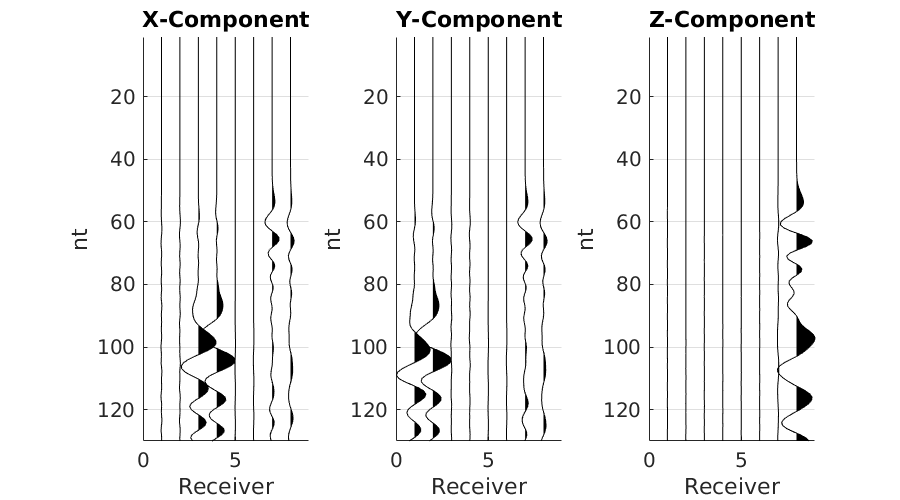

fig = figure(10); 
subplot(1,3,1);
wiggle(datax(:,:)'); 
title('X-Component','Fontsize',15);
ylabel ('nt','Fontsize',15)
xlabel ('Receiver','Fontsize',15)
grid on
set(gca,'Fontsize',15);   

subplot(1,3,2); 
wiggle(datay(:,:)');
grid on
xlabel ('Receiver','Fontsize',15)
title('Y-Component','Fontsize',15);
ylabel ('nt','Fontsize',15)
set(gca,'Fontsize',15);    

subplot(1,3,3);
wiggle(dataz(:,:)');  
title('Z-Component','Fontsize',15);
grid on
xlabel ('Receiver','Fontsize',15)
ylabel ('nt','Fontsize',15)
set(gca,'Fontsize',15);   

set(fig,'Position',[0 0, 900 500])

set(fig,'PaperPositionMode','Auto')

## Plot results - Ray tracing

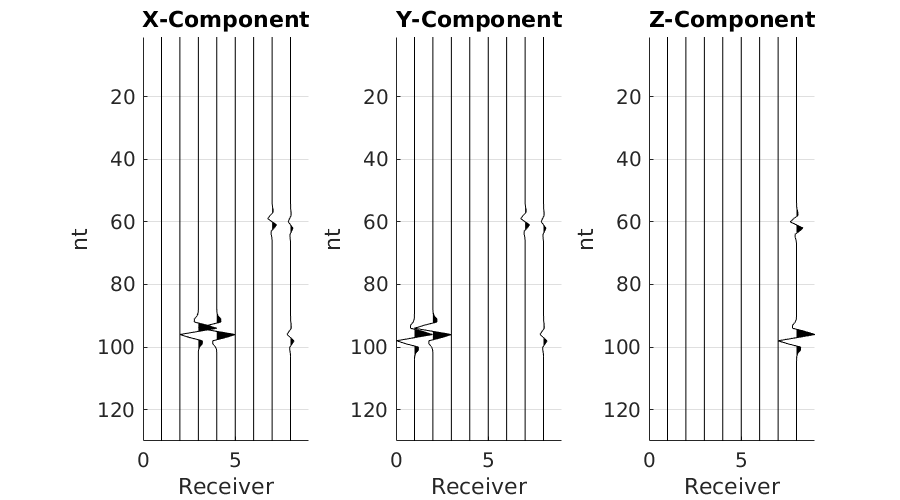

fig = figure(12); 
subplot(1,3,1);
wiggle(seis(:,:,1)'); 
title('X-Component','Fontsize',15);
ylabel ('nt','Fontsize',15)
xlabel ('Receiver','Fontsize',15)
grid on
set(gca,'Fontsize',15);   

subplot(1,3,2); 
wiggle(seis(:,:,2)');
grid on
xlabel ('Receiver','Fontsize',15)
title('Y-Component','Fontsize',15);
ylabel ('nt','Fontsize',15)
set(gca,'Fontsize',15);    

subplot(1,3,3);
wiggle(seis(:,:,3)');  
title('Z-Component','Fontsize',15);
grid on
xlabel ('Receiver','Fontsize',15)
ylabel ('nt','Fontsize',15)
set(gca,'Fontsize',15);   

set(fig,'Position',[0 0, 900 500])

set(fig,'PaperPositionMode','Auto')